# Riepilogo 06 - Incertezza in misure tipiche su segnali, nel caso di errori indipendenti identicamente distribuiti

## In sintesi

Il calcolo della WCU e della SU nelle misure di *valor medio*, *valore efficace* e *valore rettificato medio*, nel caso di errori in ingresso indipendenti identicamente distribuiti, è semplicissimo. 

Detta $U_0$, $u_0$ la WCU e la SU delle misure sui campioni in ingresso, e $U_{\theta \;}$, $u_{\theta \;}$ la WCU e la SU delle misure in uscita (di $x_{\mathrm{avg}} ,x_{\mathrm{rms}} ,x_{\mathrm{arv}}$), si hanno le seguenti formule.

Per la misura di *valor medio *$x_{\mathrm{avg}}$:

- 
$$U_{\theta \;} =U_0$$


- $u_{\theta \;} =\frac{u_0 }{\sqrt{N}}$ "formula dell'incertezza standard della media"

Per la misura di *valore efficace *$x_{\mathrm{rms}}$:

- 
$$U_{\theta \;} =U_0 \frac{x_{\mathrm{arv}} }{x_{\mathrm{rms}} }=\frac{U_0 }{FF}$$


- $u_{\theta \;} =\frac{u_0 }{\sqrt{N}}$ "formula dell'incertezza standard della media"

Per la misura di *valore rettificato medio *$x_{\mathrm{arv}}$:

- 
$$U_{\theta \;} =U_0$$


- $u_{\theta \;} =\frac{u_0 }{\sqrt{N}}$ "formula dell'incertezza standard della media"

## Oggetto degli esercizi

In questi esercizi si calcola l'incertezza di alcune misure, nel caso frequente di *errori in ingresso indipendenti identicamente distribuiti (i.i.d.)*. 

Gli errori in ingresso hanno quindi tutti la stessa incertezza di caso peggiore $U_o$ e la stessa incertezza standard $u_o$. 

Poiché gli errori in ingresso sono indipendenti, è applicabile la LPU-WCU. Poiché gli errori hanno coefficienti di correlazione nulli, la loro matrice covarianza in ingresso è diagonale, ed è precisamente la matrice identità moltiplicata per una costante, $\Sigma =u_0^2 I$.

Un'altra ipotesi in questi problemi è di *considerare una sola grandezza di uscita*, per cui la matrice dei coefficienti di sensibilità $C$ è una matrice riga:


$$C=\left\lbrack c_1 \ldotp \cdots ,c_N \right\rbrack$$


Sotto queste ipotesi non ci sono coefficienti di correlazione in uscita da calcolare (avendosi una sola uscita), e le leggi di propagazione si semplificano molto.

In tutti i casi considerati viene calcolata la WCU e la SU, e si constata che:

- la WCU non diminuisce al crescere di $N$, ed è dello stesso ordine di grandezza di $U_0$;

- la SU, invece, diminuisce come $\frac{1}{\sqrt{N}}$, ed è dell'ordine di grandezza di $\frac{u_0 }{\sqrt{N}}$

- La pdf dell'errore in uscita è quindi *una campana a code finite, le cui code non variano al crescere di *$N$*, ma che si restringe al crescere di N*.

In questa situazione valutare l'incertezza mediante la WCU è sempre troppo pessimistico e irrealistico, tranne quanto $N$ è molto piccolo (dell'ordine di $N=1\div 3$).  Quando $N>3$, l'incertezza estesa valutata con una probabilità di copertura del 95% è molto più piccola della WCU. 

In generale, l'ordine di grandezza del rapporto $k_{\max } =\frac{U_{\theta \;} }{u_{\theta \;} }$ è pari a$\frac{U_0 }{u_0 }\sqrt{N}$, quindi per $N=4$ si ha $k_{\max } >2$, per $N=100$ si ha $k_{\max } >10$. Ricordiamo che per applicare correttamente l'approssimazione gaussiana al calcolo dell'incertezza estesa con $\textrm{cp}=95%$ è sufficiente che sia $k_{\max \;} >2$, per esempio $k_{\max } \cong 2\ldotp 5$

## Equazioni valide per tutti i casi considerati

La LPU-WCU generale, $U_{\theta \;} =\mathrm{abs}\left(C\right)\;U$, nel caso di errori i.i.d. con $U=\left\lbrack U_0 ;\cdots ;U_0 \right\rbrack$ si riduce a:


$$U_{\theta \;} =U_0 \sum_{n=1}^N |c_n |=c_U \;U_0$$


con $c_U =\sum_{n=1}^N |c_n |$ (somma dei moduli degli elementi di $C$ vettore riga).

La LPU generale, $\Sigma_{\theta \;} =C\;\Sigma \;C^T$, nel caso di errori i.i.d. con $\Sigma =u_0^2 I$, si riduce a:


$$u_{\theta \;} =u\sqrt{\sum_{n=1}^N c_n^2 \;}=c_u \;u\;$$


con $c_u =\sqrt{\sum_{n=1}^N c_n^2 \;}$ (somma quadratica degli elementi di $C$ vettore riga).

Quindi, per ogni caso considerato, per calcolare WCU e SU è sufficiente il calcolo dei due coefficienti $c_U$ e $c_u$. 

Il calcolo di EU equivale a quello di SU, perché si applica l'approssimazione gaussiana: $U_{\theta ,\textrm{cp}} =k_{\textrm{cp}} \;u_{\theta \;}$ con $k_{cp} =\Phi {\;}^{-1} \left(\frac{1+cp}{2}\right)$

## 1 - Incertezza nella misura di *valor medio* con errori i.i.d.

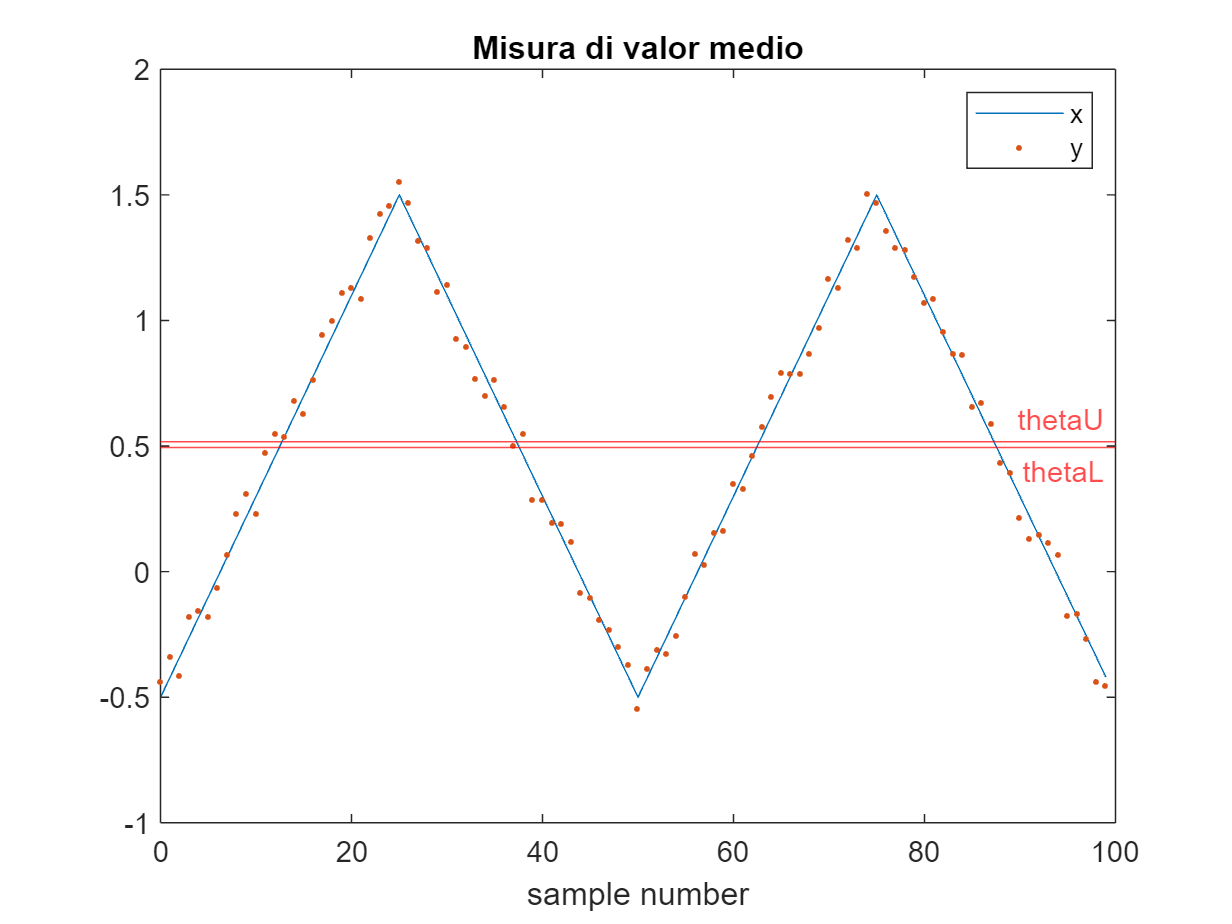

$x_{\textrm{avg}} =\frac{1}{N}\sum_{n=1}^N x_n$ valor medio

$C_{\textrm{avg}} =\frac{1}{N}\left\lbrack 1,\cdots ,1\right\rbrack$ coefficienti di sensibilità

Coefficienti $c_U$ e $c_u$:


$$c_{U,\textrm{avg}} =\sum_{n=1}^N \frac{1}{N}=1$$



$$c_{u,\textrm{avg}} =\sqrt{\sum_{n=1}^N \frac{1}{N^2 }}=\sqrt{\;\frac{N}{N^2 }}=\frac{1}{\sqrt{N}}$$


In definitiva, misurando il **valor medio **con errori in ingresso i.i.d.:

- la WCU non diminuisce con il numero di campioni;

- la SU diminuisce con il numero di campioni, come $\frac{1}{\sqrt{N}}$.

Si ha, in particolare:

- 
$$U_{\theta \;} =U_0$$


- $u_{\theta \;} =\frac{u_0 }{\sqrt{N}}$ questa formula ricorre in molti casi, e prende il nome di "formula dell'incertezza standard della media"

La pdf dell'errore in uscita è *una campana a code finite che si restringe al crescere di N*.

% Si misura un segnale come in figura. 
% I valori veri dei campioni in ingresso sono il vettore colonna x (sconosciuto)
% I valori misurati dei campioni sono il vettore colonna y (fornito).
% Gli errori in ingresso sono indipendenti identicamente distribuiti (i.i.d.), con incertezza di
% caso peggiore U0.
% Si calcola il VALORE MEDIO (theta_hat) dei campioni y, come misura del valore medio (theta) dei campioni x.

% Dati
% U0 = incertezza di caso peggiore in ingresso, scalare
% y = valori misurati in ingresso, vettore colonna

% Domande
% u0 = incertezza standard in ingresso, scalare
% theta_hat = valore misurato in uscita
% U_theta = WCU di theta
% u_theta = SU di theta
% U95_theta = EU di theta, con cp = 95%
% thetaU = limite superiore dell'intervallo di confidenza per theta, con cp = 95%
% thetaL = limite inferiore dell'intervallo di confidenza per theta, con cp = 95%
% kmax = massimo fattore di copertura applicabile a u_theta

% Codice iniziale
clear
rng('default')
N = 1e2;
Np = 2;
Fx = Np/N;
n = (0:N-1)';
x = sawtooth(2*pi*Fx*n,0.5) + 0.5;
U0 = 0.1

U0 =    100.0000e-003

y = x + unifrnd(-U0,U0,[N,1])

y =   -437.0553e-003
  -338.8416e-003
  -414.6026e-003
  -177.3248e-003
  -153.5282e-003
  -180.4919e-003
   -64.3004e-003
    69.3763e-003
   231.5014e-003
   312.9777e-003


### Soluzione

Tutto lo svolgimento è una semplice applicazione delle formule teoriche

u0 = U0/sqrt(3) % poiché conosciamo solo la WCU, assumiamo pdf uniforme

u0 =     57.7350e-003

y_avg = mean(y);
theta_hat = y_avg

theta_hat =    505.5989e-003

U_theta = U0

U_theta =    100.0000e-003

u_theta = u0/sqrt(N) % incertezza standard della media

u_theta =      5.7735e-003

k95 = norminv((1+0.95)/2)

k95 =      1.9600e+000

U95_theta = k95*u_theta

U95_theta =     11.3159e-003

Questo calcolo non è richiesto dalla traccia: lo eseguiamo per constatare che l'incertezza di caso peggiore è enormemente maggiore dell'incertezza estesa (di circa 9 volte)

U_theta/U95_theta

ans =      8.8372e+000

thetaU = theta_hat + U95_theta

thetaU =    516.9148e-003

thetaL = theta_hat - U95_theta

thetaL =    494.2830e-003

kmax = U_theta/u_theta

kmax =     17.3205e+000

% Grafico per figura
theta = mean(x)

theta =    500.0000e-003

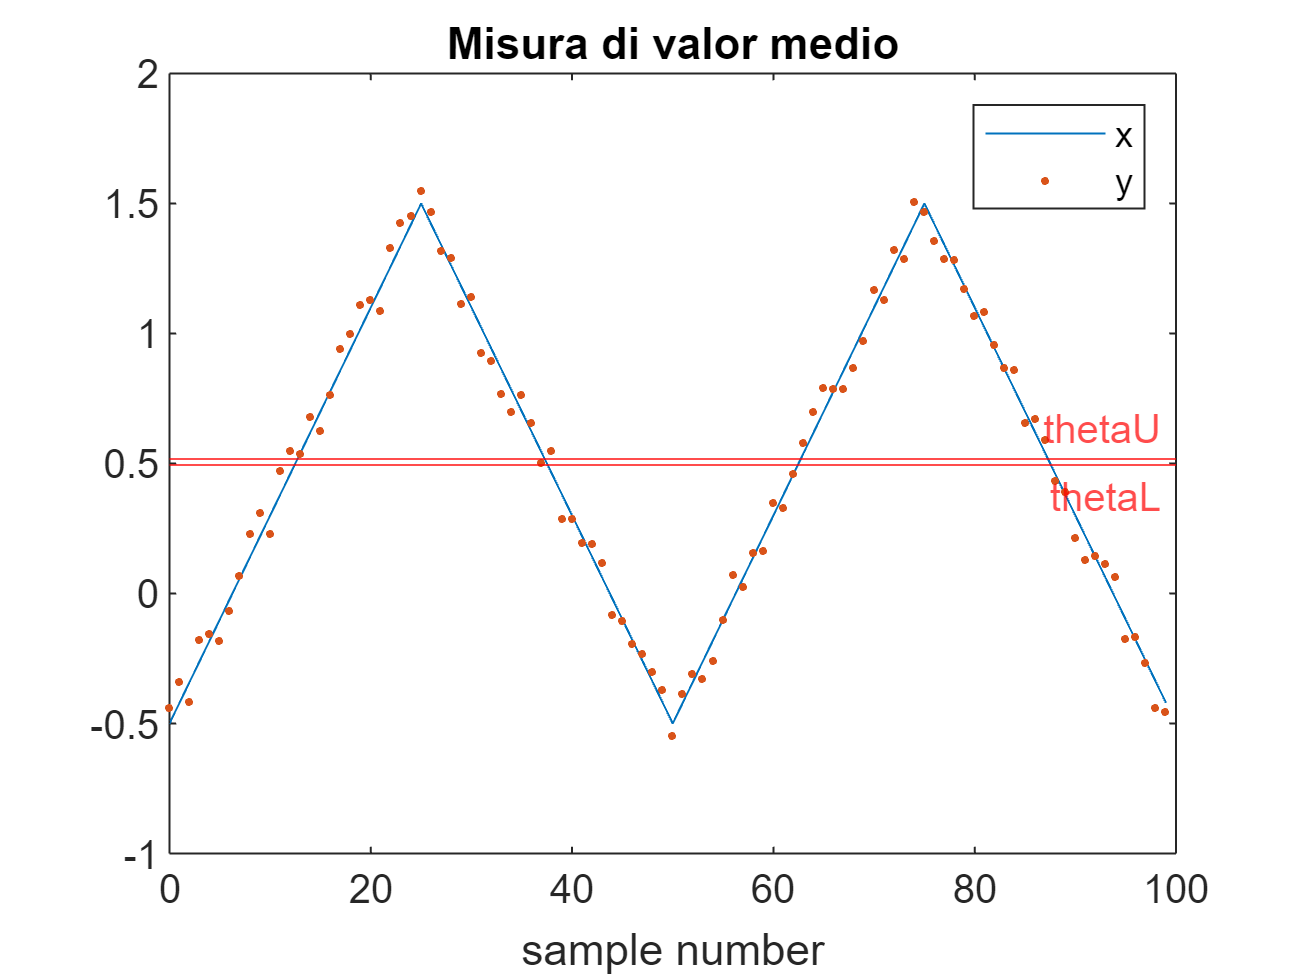

plot(n,x,n,y,'.')
yline(thetaU,'r-','thetaU','LabelVerticalAlignment','top')
yline(thetaL,'r-','thetaL','LabelVerticalAlignment','bottom')
xlabel('sample number')
legend('x','y')
title('Misura di valor medio')

## 2 - Incertezza nella misura di *valore efficace* con errori i.i.d.

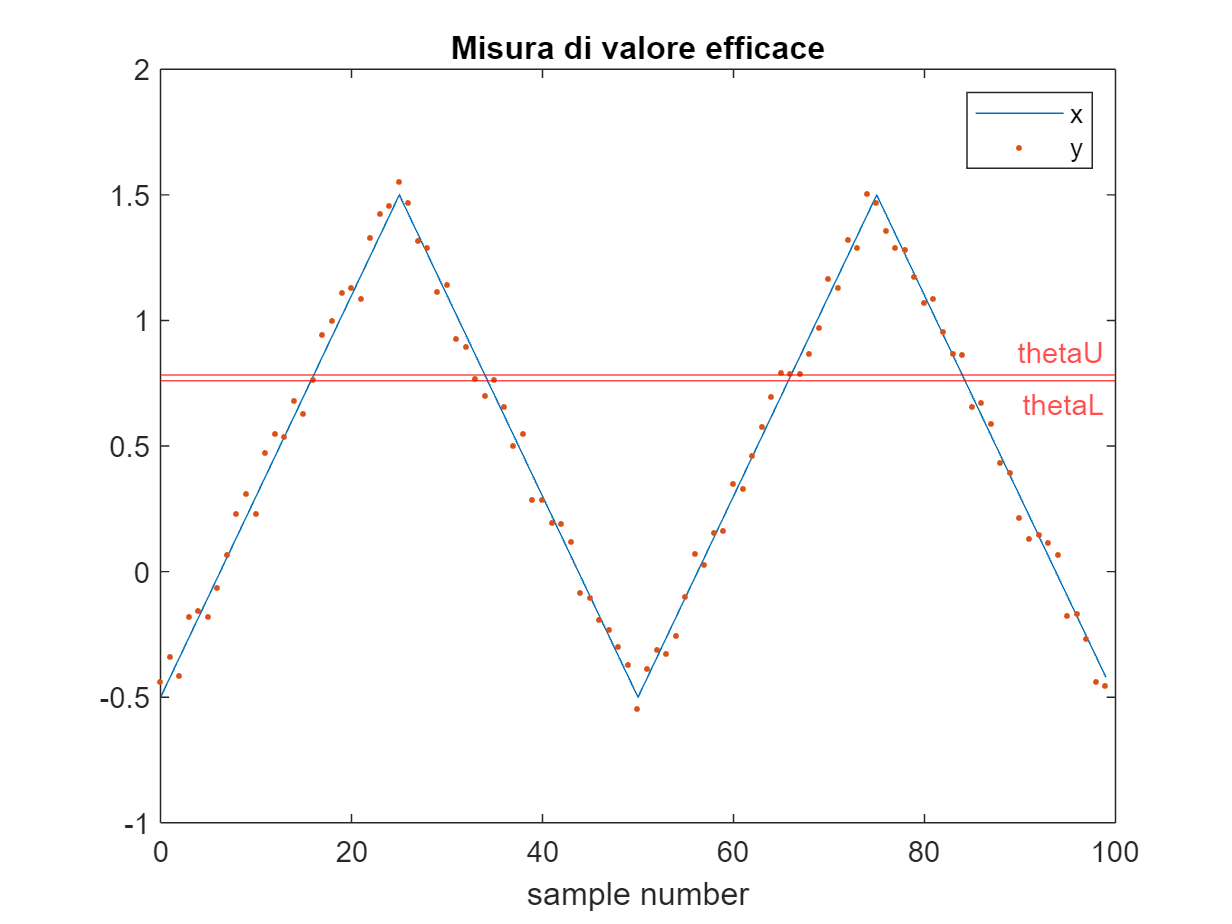

 $x_{\textrm{rms}} =\sqrt{\;\;\frac{1}{N}\sum_{n=1}^N x_n^2 }$ valore efficace

$C_{\textrm{rms}} =\frac{1}{N\;x_{\textrm{rms}} }\left\lbrack x_1 ,\cdots ,x_N \right\rbrack$ coefficienti di sensibilità

Coefficienti $c_U$ e $c_u$:


$$c_{U,\textrm{rms}} =\frac{1}{x_{\textrm{rms}} }\;\frac{1}{N}\sum_{n=1}^N |x_n |=\frac{x_{\textrm{arv}} }{x_{\textrm{rms}} }$$



$$c_{u,\textrm{rms}} =\sqrt{\frac{1}{x_{\textrm{rms}}^2 }\;\frac{1}{N^2 }\sum_{n=1}^N x_n^2 }=$$

$$\frac{1}{x_{\textrm{rms}} }\;\frac{1}{\sqrt{N}}\sqrt{\frac{1}{N}\sum_{n=1}^N x_n^2 }=\frac{1}{x_{\textrm{rms}} }\;\frac{1}{\sqrt{N}}\;x_{\textrm{rms}} =\frac{1}{\sqrt{N}}$$


In definitiva, misurando il **valore efficace **con errori in ingresso i.i.d.:

- la WCU non diminuisce con il numero di campioni;

- la SU diminuisce con il numero di campioni, come $\frac{1}{\sqrt{N}}$.

Si ha, in particolare:

- 
$$U_{\theta \;} =U_0 \frac{x_{\mathrm{arv}} }{x_{\mathrm{rms}} }$$


- $u_{\theta \;} =\frac{u_0 }{\sqrt{N}}$ ritroviamo, per il valore efficace, la formula dell'incertezza standard della media

La pdf dell'errore in uscita è *una campana a code finite che si restringe al crescere di N*.

Nota informativa: in questa misura la WCU in uscita è pari alla WCU in ingresso divisa per il *fattore di forma *del segnale, che per definizione è il rapporto $\textrm{FF}=\frac{x_{\textrm{rms}} }{x_{\textrm{arv}} }$. Il fattore di forma è normalmente vicino all'unità: a titolo di esempio, per un segnale sinusoidale si ha $\textrm{FF}=\frac{\pi }{2\sqrt{2}}\cong 1\ldotp 11$, per un segnale triangolare $\textrm{FF}=\frac{2}{\sqrt{3}}\cong 1\ldotp 15$

% Si misura un segnale come in figura. 
% I valori veri dei campioni in ingresso sono il vettore colonna x (sconosciuto)
% I valori misurati dei campioni sono il vettore colonna y (fornito).
% Gli errori in ingresso sono indipendenti identicamente distribuiti (i.i.d.), con incertezza di
% caso peggiore U0.
% Si calcola il VALORE EFFICACE (theta_hat) dei campioni y, come misura del valore efficace (theta) dei campioni x.

% Dati
% U0 = incertezza di caso peggiore in ingresso, scalare
% y = valori misurati in ingresso, vettore colonna

% Domande
% u0 = incertezza standard in ingresso, scalare
% theta_hat = valore misurato in uscita
% U_theta = WCU di theta
% u_theta = SU di theta
% U95_theta = EU di theta, con cp = 95%
% thetaU = limite superiore dell'intervallo di confidenza per theta, con cp = 95%
% thetaL = limite inferiore dell'intervallo di confidenza per theta, con cp = 95%
% kmax = massimo fattore di copertura applicabile a u_theta

% Codice iniziale
clear
rng('default')
N = 1e2;
Np = 2;
Fx = Np/N;
n = (0:N-1)';
x = sawtooth(2*pi*Fx*n,0.5) + 0.5;
U0 = 0.1

U0 =    100.0000e-003

y = x + unifrnd(-U0,U0,[N,1])

y =   -437.0553e-003
  -338.8416e-003
  -414.6026e-003
  -177.3248e-003
  -153.5282e-003
  -180.4919e-003
   -64.3004e-003
    69.3763e-003
   231.5014e-003
   312.9777e-003


### Soluzione

Tutto lo svolgimento è una semplice applicazione delle formule teoriche

u0 = U0/sqrt(3) % poiché conosciamo solo la WCU, assumiamo pdf uniforme

u0 =     57.7350e-003

y_rms = sqrt(mean(y.^2));
theta_hat = y_rms

theta_hat =    771.6983e-003

y_arv = mean(abs(y)); % serve per calcolare U_theta
U_theta = U0*y_arv/y_rms

U_theta =     82.2549e-003

u_theta = u0/sqrt(N) % incertezza standard della media

u_theta =      5.7735e-003

k95 = norminv((1+0.95)/2)

k95 =      1.9600e+000

U95_theta = k95*u_theta

U95_theta =     11.3159e-003

Questo calcolo non è richiesto dalla traccia: lo eseguiamo per constatare che l'incertezza di caso peggiore è enormemente maggiore dell'incertezza estesa (di circa 7 volte)

U_theta/U95_theta

ans =      7.2690e+000

thetaU = theta_hat + U95_theta

thetaU =    783.0141e-003

thetaL = theta_hat - U95_theta

thetaL =    760.3824e-003

kmax = U_theta/u_theta

kmax =     14.2470e+000

% Grafico per figura
theta = mean(x)

theta =    500.0000e-003

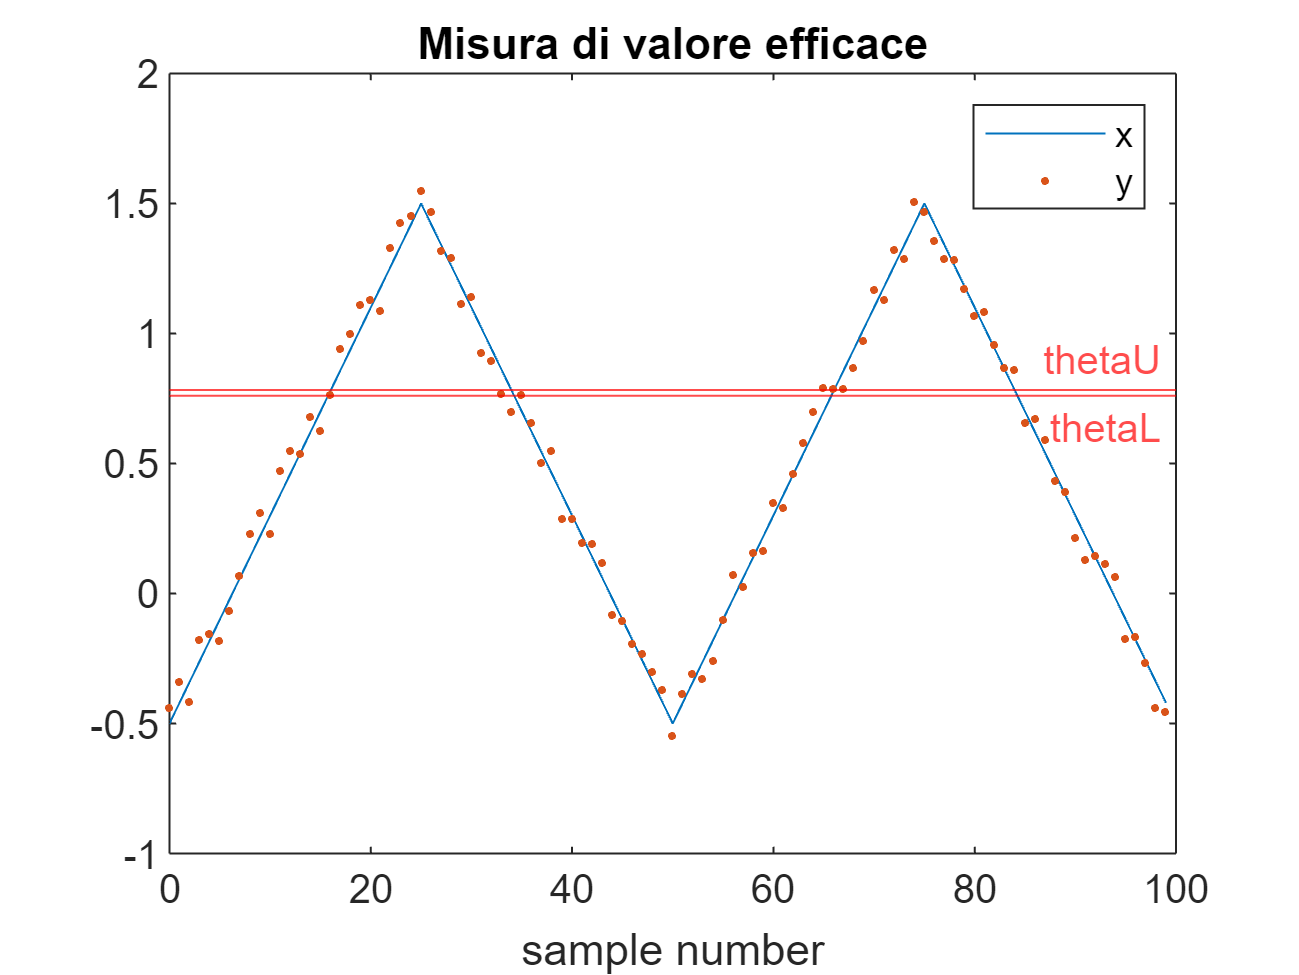

plot(n,x,n,y,'.')
yline(thetaU,'r-','thetaU','LabelVerticalAlignment','top')
yline(thetaL,'r-','thetaL','LabelVerticalAlignment','bottom')
xlabel('sample number')
legend('x','y')
title('Misura di valore efficace')

## 3 - Incertezza nella misura di *valore rettificato* *medio *con errori i.i.d.

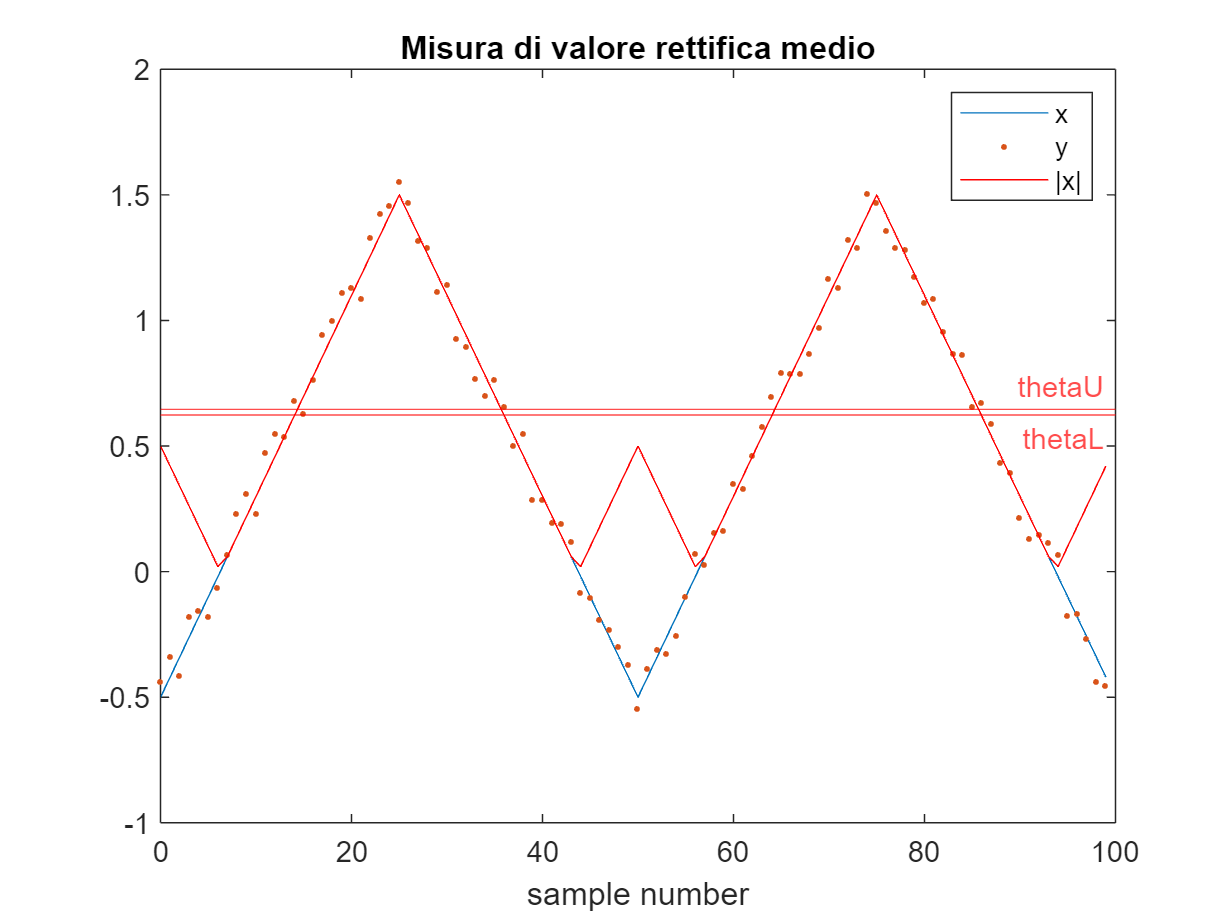

 $x_{\textrm{arv}} =\frac{1}{N}\sum_{n=1}^N |x_n |$ valore rettificato medio

$C_{\textrm{arv}} =\frac{1}{N}\left\lbrack \textrm{sign}\left(x_1 \right),\cdots ,\textrm{sign}\left(x_N \right)\right\rbrack$ coefficienti di sensibilità

Coefficienti $c_U$ e $c_u$:


$$c_{U,\textrm{arv}} =\frac{1}{N}\sum_{n=1}^N |\textrm{sign}\left(x_n \right)|=\frac{1}{N}\sum_{n=1}^N 1=1$$



$$c_{u,\textrm{arv}} =\sqrt{\;\frac{1}{N^2 }\sum_{n=1}^N {\textrm{sign}\left(x_n \right)}^2 }=$$

$$\;\frac{1}{\sqrt{N}}\sqrt{\frac{1}{N}\sum_{n=1}^N 1}=\frac{1}{\sqrt{N}}$$


In definitiva, misurando il **la potenza del segnale **con errori in ingresso i.i.d.:

- la WCU non diminuisce con il numero di campioni;

- la SU diminuisce con il numero di campioni, come $\frac{1}{\sqrt{N}}$.

Si ha, in particolare:

- 
$$U_{\theta \;} =U_0$$


- $u_{\theta \;} =\frac{u_0 }{\sqrt{N}}$ anche qui ritroviamo la formula dell'incertezza standard della media

Si noti che le due formule sono identiche a quelle per il valore medio.

La pdf dell'errore in uscita è *una campana a code finite che si restringe al crescere di N*.

% Si misura un segnale come in figura. 
% I valori veri dei campioni in ingresso sono il vettore colonna x (sconosciuto)
% I valori misurati dei campioni sono il vettore colonna y (fornito).
% Gli errori in ingresso sono indipendenti identicamente distribuiti (i.i.d.), con incertezza di
% caso peggiore U0.
% Si calcola il VALORE RETTIFICATO MEDIO (theta_hat) dei campioni y, come misura del valore rettificato medio
% (theta) dei campioni x.

% Dati
% U0 = incertezza di caso peggiore in ingresso, scalare
% y = valori misurati in ingresso, vettore colonna

% Domande
% u0 = incertezza standard in ingresso, scalare
% theta_hat = valore misurato in uscita
% U_theta = WCU di theta
% u_theta = SU di theta
% U95_theta = EU di theta, con cp = 95%
% thetaU = limite superiore dell'intervallo di confidenza per theta, con cp = 95%
% thetaL = limite inferiore dell'intervallo di confidenza per theta, con cp = 95%
% kmax = massimo fattore di copertura applicabile a u_theta

% Codice iniziale
clear
rng('default')
N = 1e2;
Np = 2;
Fx = Np/N;
n = (0:N-1)';
x = sawtooth(2*pi*Fx*n,0.5) + 0.5;
U0 = 0.1

U0 =    100.0000e-003

y = x + unifrnd(-U0,U0,[N,1])

y =   -437.0553e-003
  -338.8416e-003
  -414.6026e-003
  -177.3248e-003
  -153.5282e-003
  -180.4919e-003
   -64.3004e-003
    69.3763e-003
   231.5014e-003
   312.9777e-003


### Soluzione

Tutto lo svolgimento è una semplice applicazione delle formule teoriche

u0 = U0/sqrt(3) % poiché conosciamo solo la WCU, assumiamo pdf uniforme

u0 =     57.7350e-003

y_arv = mean(abs(y));
theta_hat = y_arv

theta_hat =    634.7597e-003

U_theta = U0 % come nella misura di valore medio

U_theta =    100.0000e-003

u_theta = u0/sqrt(N) % incertezza standard della media

u_theta =      5.7735e-003

k95 = norminv((1+0.95)/2)

k95 =      1.9600e+000

U95_theta = k95*u_theta

U95_theta =     11.3159e-003

Questo calcolo non è richiesto dalla traccia: lo eseguiamo per constatare che l'incertezza di caso peggiore è enormemente maggiore dell'incertezza estesa (di circa 9 volte)

U_theta/U95_theta

ans =      8.8372e+000

thetaU = theta_hat + U95_theta

thetaU =    646.0755e-003

thetaL = theta_hat - U95_theta

thetaL =    623.4438e-003

kmax = U_theta/u_theta

kmax =     17.3205e+000

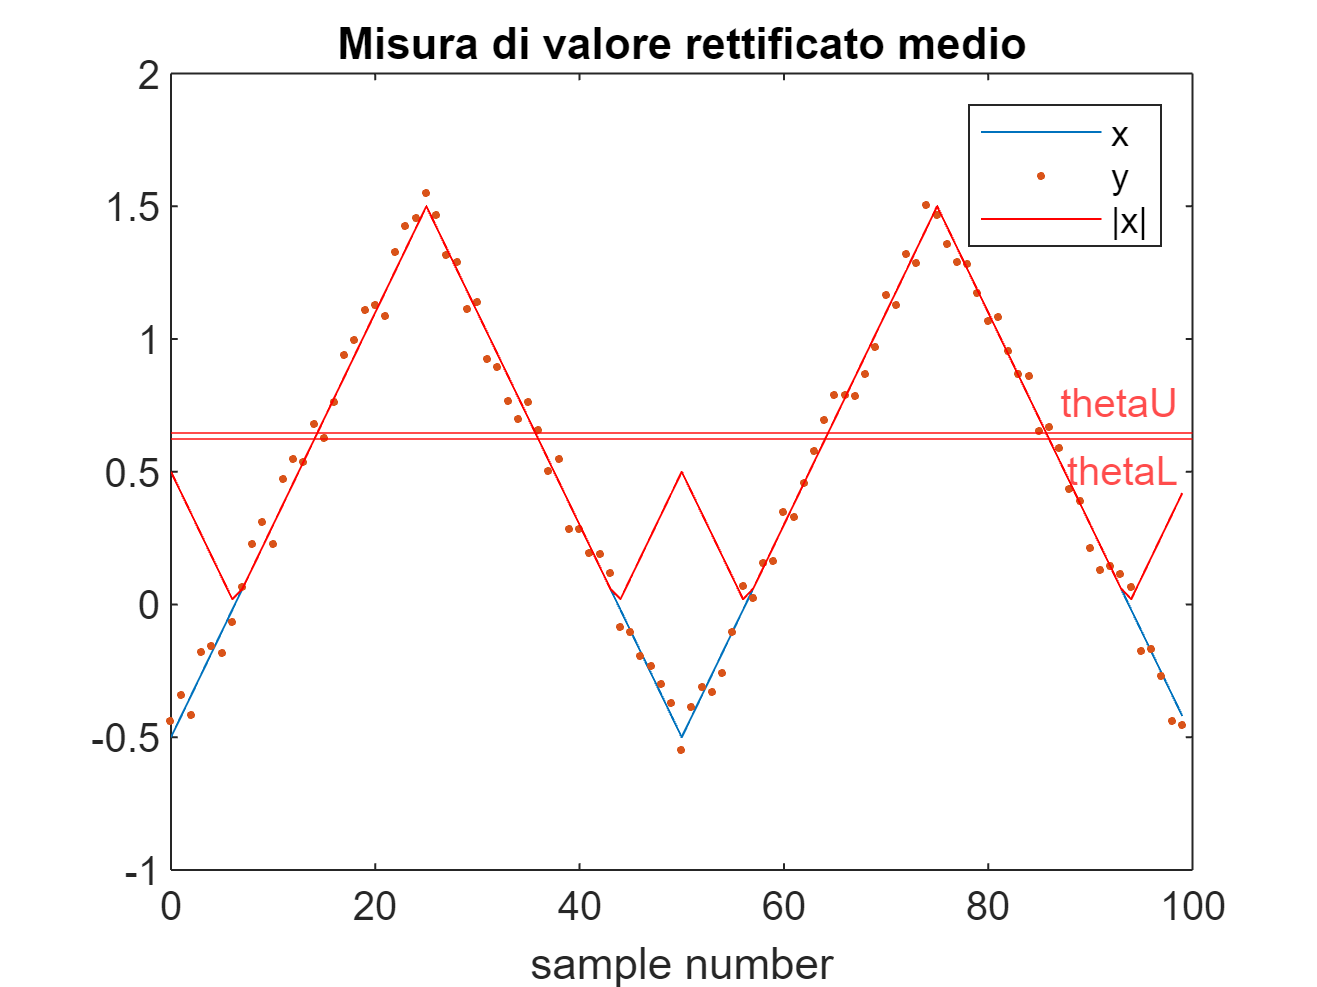

% Grafico per figura
plot(n,x,n,y,'.',n,abs(x),'r')
yline(thetaU,'r-','thetaU','LabelVerticalAlignment','top')
yline(thetaL,'r-','thetaL','LabelVerticalAlignment','bottom')
xlabel('sample number')
legend('x','y','|x|')
title('Misura di valore rettificato medio')

% 